## Arm Circle Vertical

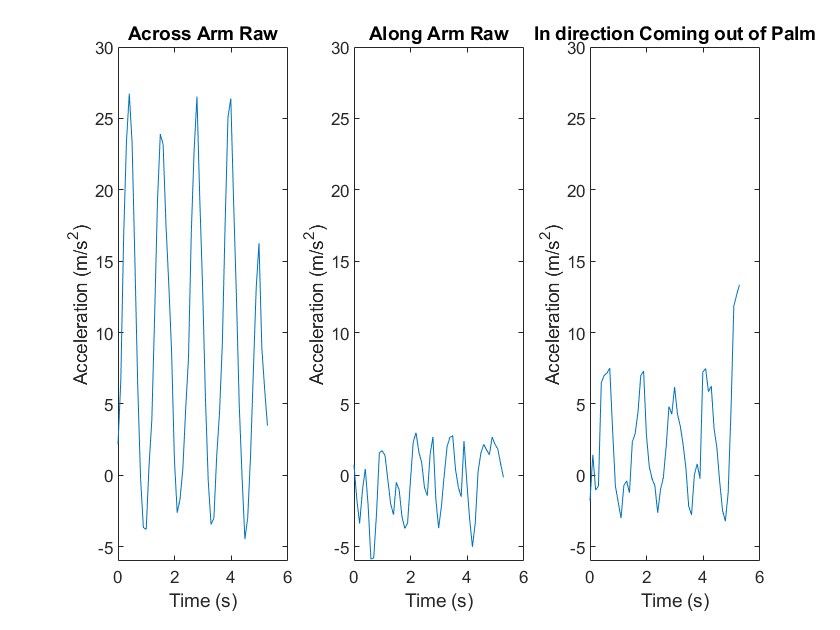

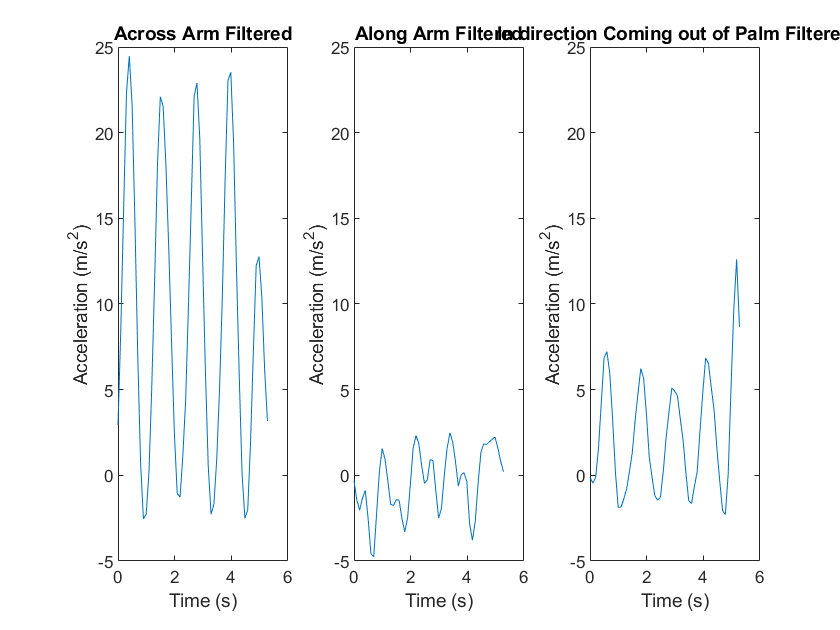

% Load Data
[ArmMotionData]=ParseMatlabApp('arm_circle_verticle2.mat');

% Index data to get rid of start and end
time = ArmMotionData.t_Accel(10:63);
arm_acceleration = ArmMotionData.Accel(10:63, :);

% Moving Average Filter
x = arm_acceleration(:,1);
y = arm_acceleration(:,2);
z = arm_acceleration(:,3);
arm_accelerationx = [x(1) + x(2); x(1:end-2) + x(2:end-1) + x(3:end); x(end-1) + x(end)]/3;
arm_accelerationy = [y(1) + y(2); y(1:end-2) + y(2:end-1) + y(3:end); y(end-1) + y(end)]/3;
arm_accelerationz = [z(1) + z(2); z(1:end-2) + z(2:end-1) + z(3:end); z(end-1) + z(end)]/3;
arm_acceleration_filtered = [arm_accelerationx arm_accelerationy arm_accelerationz];

% Plot Time Domain
makeAccelerometerPlots([time,arm_acceleration], {'Across Arm Raw', 'Along Arm Raw', 'In direction Coming out of Palm'})
makeAccelerometerPlots([time,arm_acceleration_filtered], {'Across Arm Filtered', 'Along Arm Filtered', 'In direction Coming out of Palm Filtered'})


% Fourier Transform
N = length(time);
time_elapsed = time(end);
Fs = length(time)/time_elapsed;
frequencies_shifted = linspace(-Fs*pi , Fs*(pi - 2*pi/N), N) + Fs*pi/N*mod(N,2);
%^^ based on lowest and highest frequencies we found above
%^^ mod is to account for if its even or odd
fourier_frequenciesx = fftshift(fft(arm_acceleration_filtered(:,1)));
fourier_frequenciesy = fftshift(fft(arm_acceleration_filtered(:,2)));
fourier_frequenciesz = fftshift(fft(arm_acceleration_filtered(:,3)));

% Plot Fourier Transformations
% converts from rad/s to bpm
convert_to_bpm = 1/0.10471975499997

convert_to_bpm = 9.5493

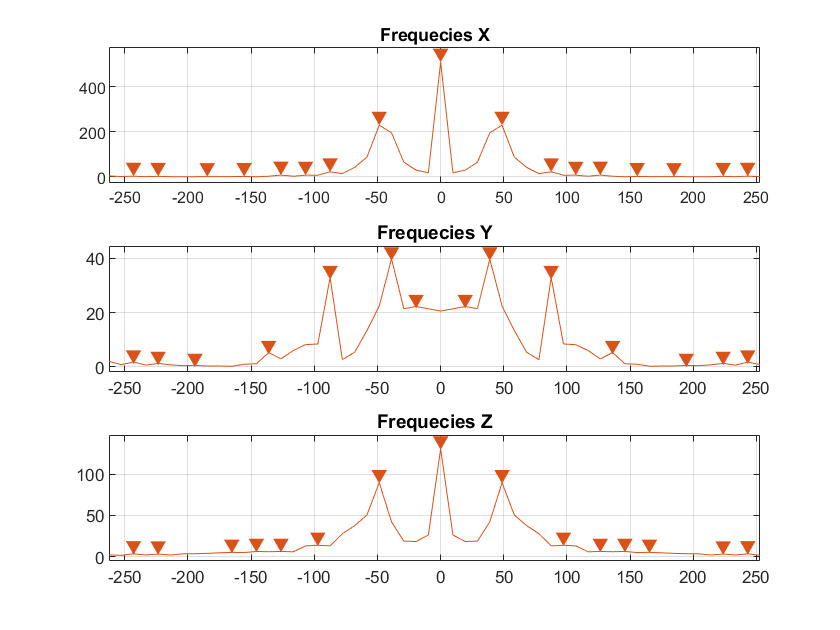


% Subplot 1
clf;
subplot(3, 1, 1);
plot(frequencies_shifted*convert_to_bpm,abs(fourier_frequenciesx));
hold on
findpeaks(abs(fourier_frequenciesx), frequencies_shifted*convert_to_bpm)
hold off
[pks,locs] = findpeaks(abs(fourier_frequenciesx), frequencies_shifted);
title("Frequecies X")

% Subplot 2
subplot(3, 1, 2);
plot(frequencies_shifted*convert_to_bpm,abs(fourier_frequenciesy));
hold on
findpeaks(abs(fourier_frequenciesy), frequencies_shifted*convert_to_bpm)
hold off
title("Frequecies Y")

% Subplot 3
subplot(3, 1, 3);
plot(frequencies_shifted*convert_to_bpm,abs(fourier_frequenciesz));
hold on
findpeaks(abs(fourier_frequenciesz), frequencies_shifted*convert_to_bpm)
hold off
title("Frequecies Z")

## Arm Circle Horizontal

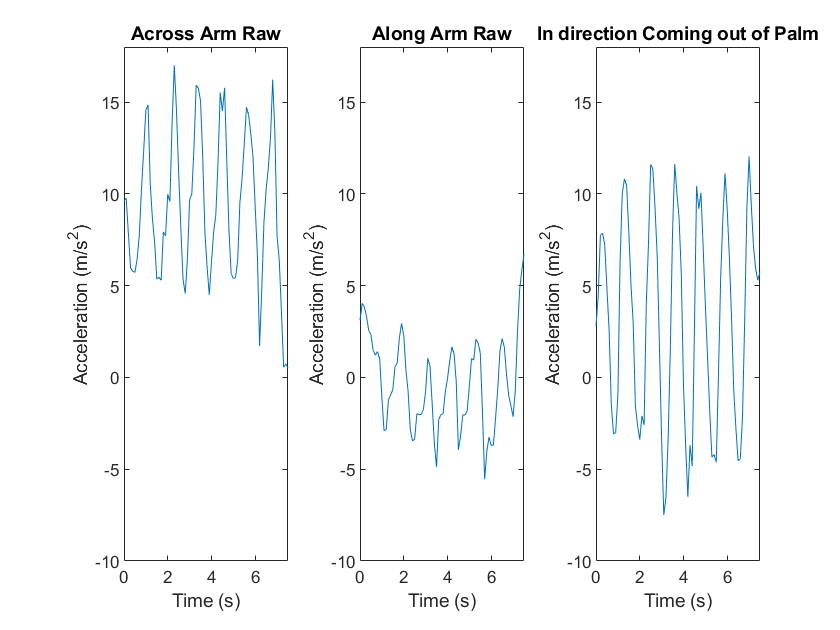

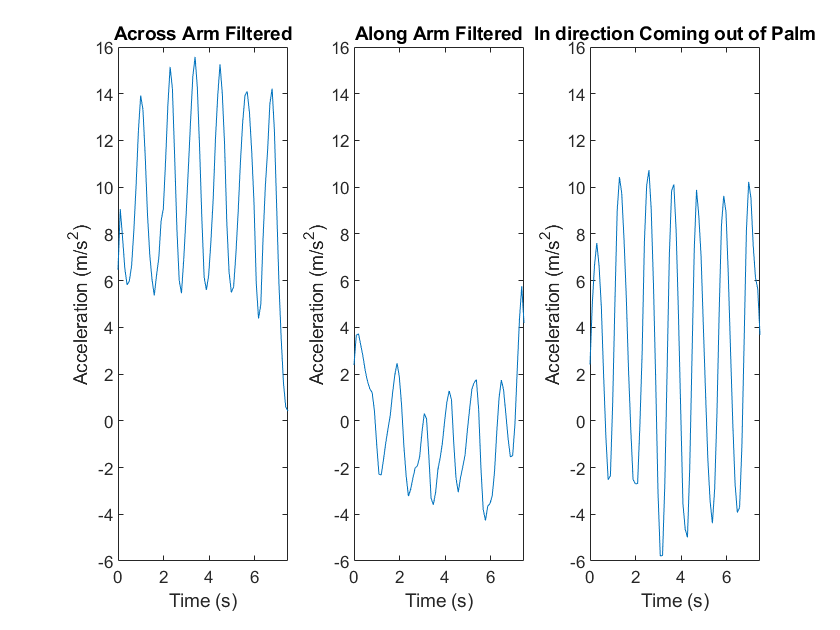

% Load Data
[ArmMotionData]=ParseMatlabApp('arm_circle_horizontal.mat');

% Index data to get rid of start and end
time = ArmMotionData.t_Accel(:);
arm_acceleration = ArmMotionData.Accel(:, :);

% Moving Average Filter
x = arm_acceleration(:,1);
y = arm_acceleration(:,2);
z = arm_acceleration(:,3);
arm_accelerationx = [x(1) + x(2); x(1:end-2) + x(2:end-1) + x(3:end); x(end-1) + x(end)]/3;
arm_accelerationy = [y(1) + y(2); y(1:end-2) + y(2:end-1) + y(3:end); y(end-1) + y(end)]/3;
arm_accelerationz = [z(1) + z(2); z(1:end-2) + z(2:end-1) + z(3:end); z(end-1) + z(end)]/3;
arm_acceleration_filtered = [arm_accelerationx arm_accelerationy arm_accelerationz];

% Plot Time Domain
makeAccelerometerPlots([time,arm_acceleration], {'Across Arm Raw', 'Along Arm Raw', 'In direction Coming out of Palm'})
makeAccelerometerPlots([time,arm_acceleration_filtered], {'Across Arm Filtered', 'Along Arm Filtered', 'In direction Coming out of Palm'})


% Fourier Transform
N = length(time);
time_elapsed = time(end);
Fs = length(time)/time_elapsed;
frequencies_shifted = linspace(-Fs*pi , Fs*(pi - 2*pi/N), N) + Fs*pi/N*mod(N,2);
%^^ based on lowest and highest frequencies we found above
%^^ mod is to account for if its even or odd
fourier_frequenciesx = fftshift(fft(arm_acceleration_filtered(:,1)));
fourier_frequenciesy = fftshift(fft(arm_acceleration_filtered(:,2)));
fourier_frequenciesz = fftshift(fft(arm_acceleration_filtered(:,3)));

% Plot Fourier Transform
% Subplot 1
clf;
subplot(3, 1, 1);
plot(frequencies_shifted,abs(fourier_frequenciesx));
hold on
findpeaks(abs(fourier_frequenciesx), frequencies_shifted,'MinPeakHeight',400)
hold off
[pks,locs] = findpeaks(abs(fourier_frequenciesx), frequencies_shifted);
title("Frequecies X")

% Subplot 2
subplot(3, 1, 2);
plot(frequencies_shifted,abs(fourier_frequenciesy));
hold on
findpeaks(abs(fourier_frequenciesy), frequencies_shifted,'MinPeakHeight',200)

hold off
title("Frequecies Y")

% Subplot 3
subplot(3, 1, 3);
plot(frequencies_shifted,abs(fourier_frequenciesz));
hold on
findpeaks(abs(fourier_frequenciesz), frequencies_shifted,'MinPeakHeight',300)

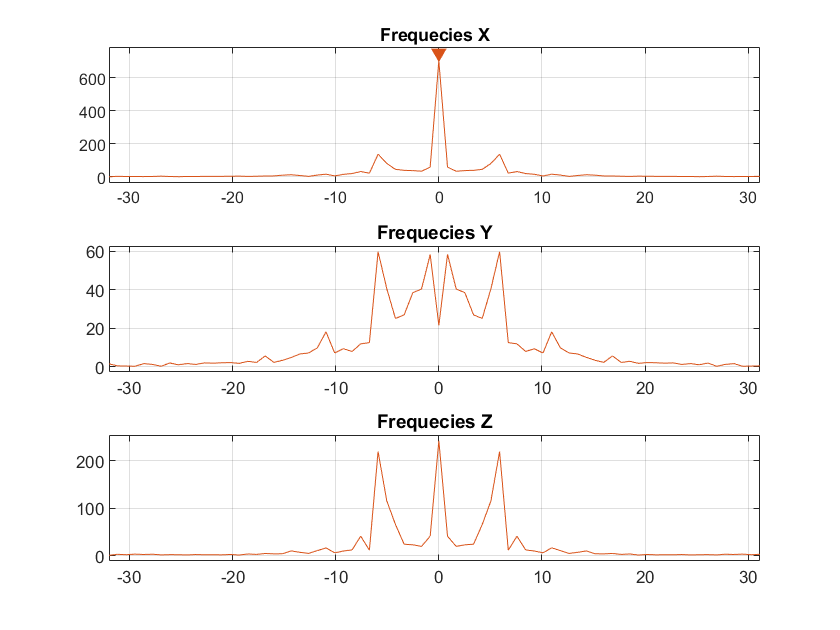

hold off
title("Frequecies Z")

## Arm Circle Get Lazy

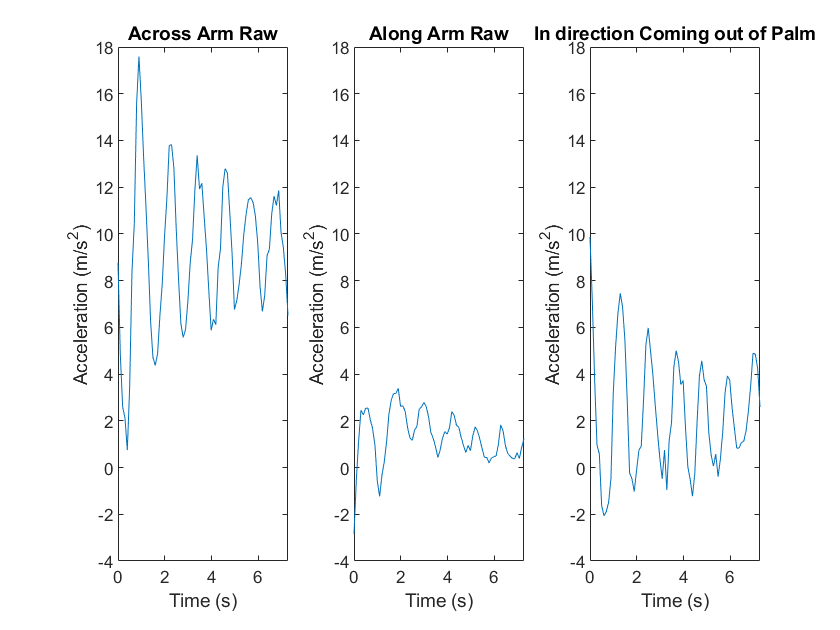

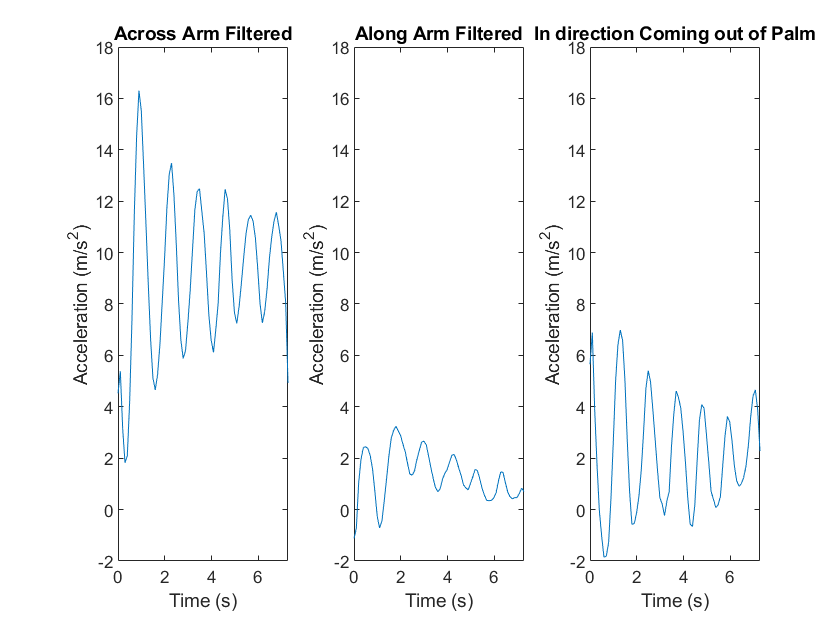

% Load Data
[ArmMotionData]=ParseMatlabApp('arm_circle_get_lazy.mat');

% Index data to get rid of start and end
time = ArmMotionData.t_Accel(17:90);
arm_acceleration = ArmMotionData.Accel(17:90, :);

% Moving Average Filter
x = arm_acceleration(:,1);
y = arm_acceleration(:,2);
z = arm_acceleration(:,3);
arm_accelerationx = [x(1) + x(2); x(1:end-2) + x(2:end-1) + x(3:end); x(end-1) + x(end)]/3;
arm_accelerationy = [y(1) + y(2); y(1:end-2) + y(2:end-1) + y(3:end); y(end-1) + y(end)]/3;
arm_accelerationz = [z(1) + z(2); z(1:end-2) + z(2:end-1) + z(3:end); z(end-1) + z(end)]/3;
arm_acceleration_filtered = [arm_accelerationx arm_accelerationy arm_accelerationz];

% Plot Time Domain
makeAccelerometerPlots([time,arm_acceleration], {'Across Arm Raw', 'Along Arm Raw', 'In direction Coming out of Palm'})
makeAccelerometerPlots([time,arm_acceleration_filtered], {'Across Arm Filtered', 'Along Arm Filtered', 'In direction Coming out of Palm'})


% Fourier Transform
N = length(time);
time_elapsed = time(end);
Fs = length(time)/time_elapsed;
frequencies_shifted = linspace(-Fs*pi , Fs*(pi - 2*pi/N), N) + Fs*pi/N*mod(N,2);
%^^ based on lowest and highest frequencies we found above
%^^ mod is to account for if its even or odd
fourier_frequenciesx = fftshift(fft(arm_acceleration_filtered(:,1)));
fourier_frequenciesy = fftshift(fft(arm_acceleration_filtered(:,2)));
fourier_frequenciesz = fftshift(fft(arm_acceleration_filtered(:,3)));

% Plot Fourier Transform
% Subplot 1
clf;
subplot(3, 1, 1);
plot(frequencies_shifted,abs(fourier_frequenciesx));
hold on
findpeaks(abs(fourier_frequenciesx), frequencies_shifted,'MinPeakHeight',400)
hold off
[pks,locs] = findpeaks(abs(fourier_frequenciesx), frequencies_shifted);
title("Frequecies X")

% Subplot 2
subplot(3, 1, 2);
plot(frequencies_shifted,abs(fourier_frequenciesy));
hold on
findpeaks(abs(fourier_frequenciesy), frequencies_shifted,'MinPeakHeight',200)

hold off
title("Frequecies Y")

% Subplot 3
subplot(3, 1, 3);
plot(frequencies_shifted,abs(fourier_frequenciesz));
hold on
findpeaks(abs(fourier_frequenciesz), frequencies_shifted,'MinPeakHeight',300)

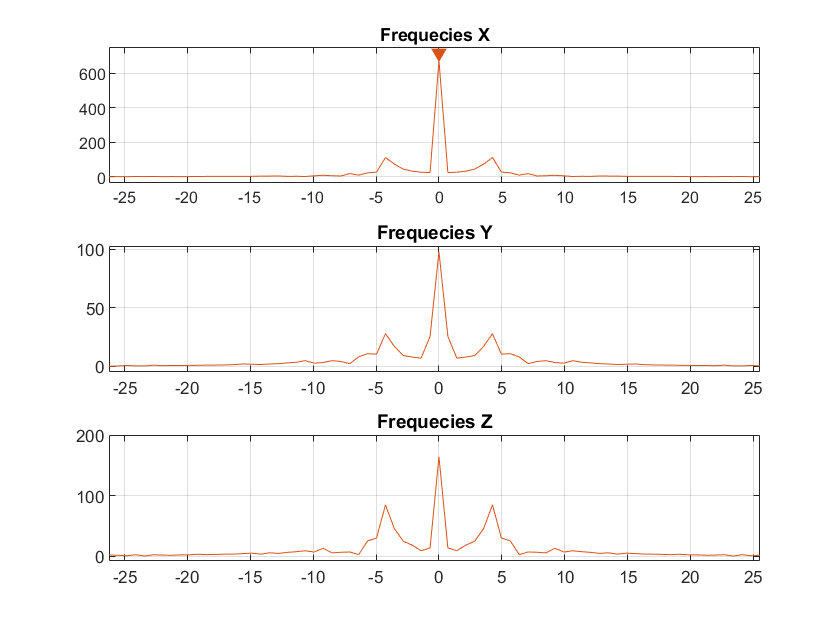

hold off
title("Frequecies Z")

## Arm Circle  Lazy

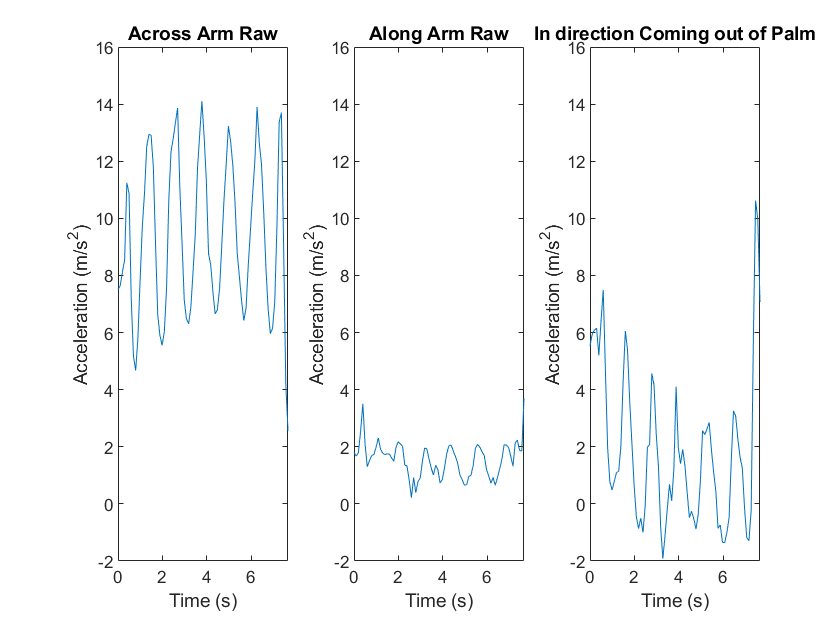

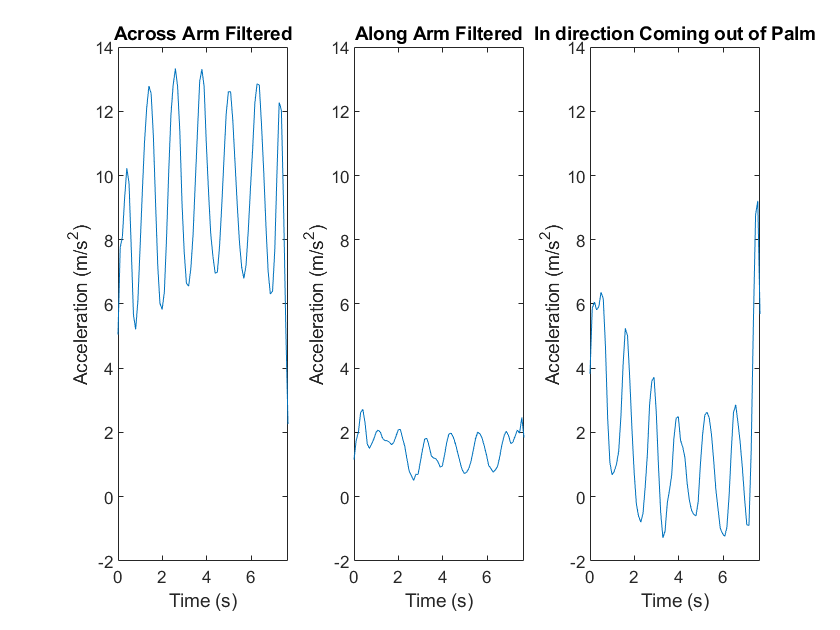

% Load Data
[ArmMotionData]=ParseMatlabApp('arm_circle_lazy.mat');

% Index data to get rid of start and end
time = ArmMotionData.t_Accel(:);
arm_acceleration = ArmMotionData.Accel(:, :);

%Moving Average Filter
x = arm_acceleration(:,1);
y = arm_acceleration(:,2);
z = arm_acceleration(:,3);
arm_accelerationx = [x(1) + x(2); x(1:end-2) + x(2:end-1) + x(3:end); x(end-1) + x(end)]/3;
arm_accelerationy = [y(1) + y(2); y(1:end-2) + y(2:end-1) + y(3:end); y(end-1) + y(end)]/3;
arm_accelerationz = [z(1) + z(2); z(1:end-2) + z(2:end-1) + z(3:end); z(end-1) + z(end)]/3;
arm_acceleration_filtered = [arm_accelerationx arm_accelerationy arm_accelerationz];


% Plot Time Domain
makeAccelerometerPlots([time,arm_acceleration], {'Across Arm Raw', 'Along Arm Raw', 'In direction Coming out of Palm'})
makeAccelerometerPlots([time,arm_acceleration_filtered], {'Across Arm Filtered', 'Along Arm Filtered', 'In direction Coming out of Palm'})


% Fourier Transform
N = length(time);
time_elapsed = time(end);
Fs = length(time)/time_elapsed;
frequencies_shifted = linspace(-Fs*pi , Fs*(pi - 2*pi/N), N) + Fs*pi/N*mod(N,2);
%^^ based on lowest and highest frequencies we found above
%^^ mod is to account for if its even or odd
fourier_frequenciesx = fftshift(fft(arm_acceleration_filtered(:,1)));
fourier_frequenciesy = fftshift(fft(arm_acceleration_filtered(:,2)));
fourier_frequenciesz = fftshift(fft(arm_acceleration_filtered(:,3)));

% Plot Fourier Transform
% Subplot 1
clf;
subplot(3, 1, 1);
plot(frequencies_shifted,abs(fourier_frequenciesx));
hold on
findpeaks(abs(fourier_frequenciesx), frequencies_shifted,'MinPeakHeight',400)
hold off
[pks,locs] = findpeaks(abs(fourier_frequenciesx), frequencies_shifted);
title("Frequecies X")

% Subplot 2
subplot(3, 1, 2);
plot(frequencies_shifted,abs(fourier_frequenciesy));
hold on
findpeaks(abs(fourier_frequenciesy), frequencies_shifted,'MinPeakHeight',200)

hold off
title("Frequecies Y")

% Subplot 3
subplot(3, 1, 3);
plot(frequencies_shifted,abs(fourier_frequenciesz));
hold on
findpeaks(abs(fourier_frequenciesz), frequencies_shifted,'MinPeakHeight',300)

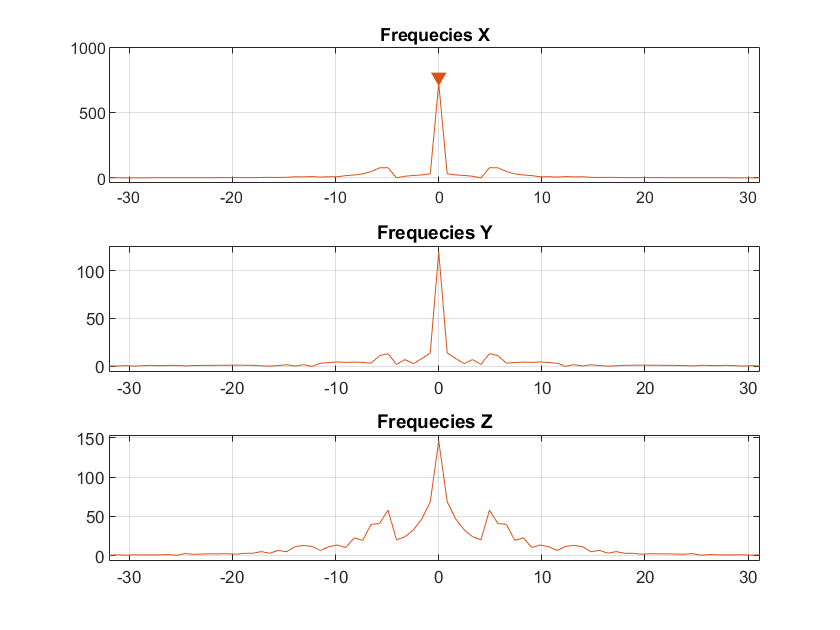

hold off
title("Frequecies Z")